# Road Conversion Algorithm

This algorithm is mainly in "map_v1/map_extend_v1.m".

These two mat file is loaded in "map_v1/map_extend_v1.m" If there is another version of the extended map, just change the "map_v1.mat" to another one.

First, load the data file which include the coordinate of several points of each road section.

load('map_v1.mat','data');

This data file can be changed and saved from drivingScenarioDesigner, which is used to extend the map under OPENDrive format.

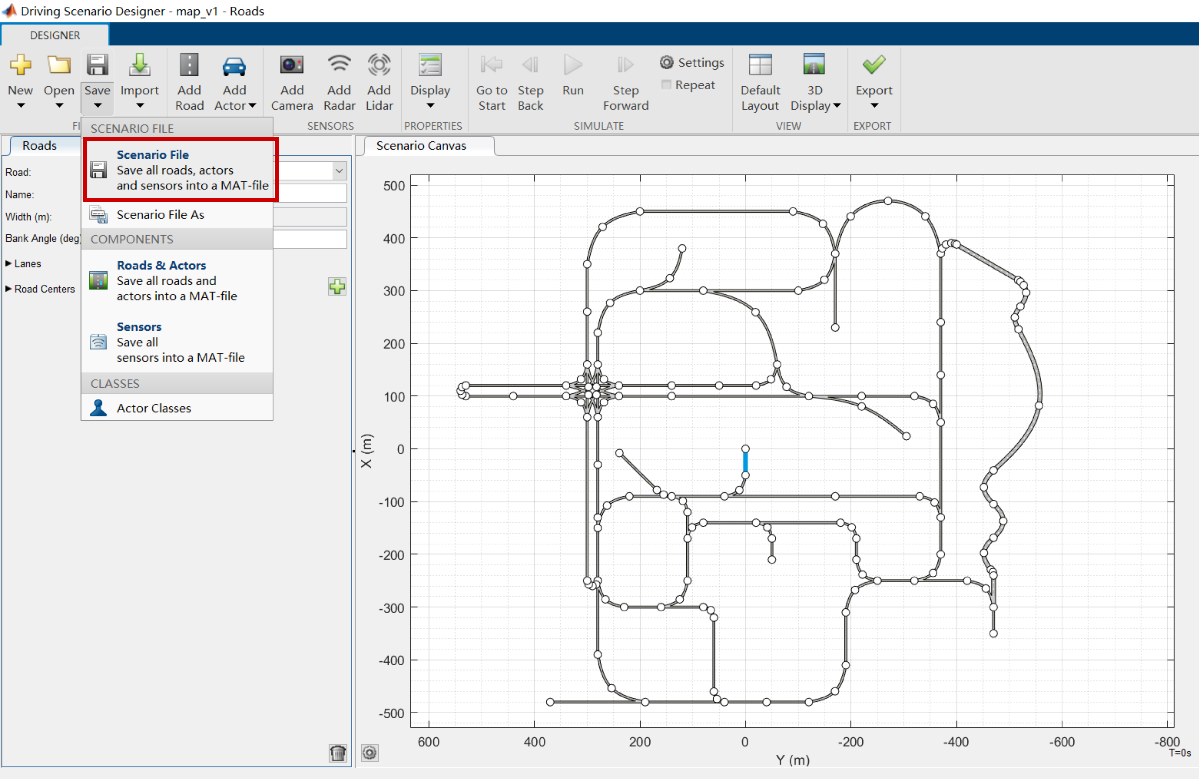

Then load the data file from original map, which is got from "Load Data/load_mobatkent.m". Because when the map is converted from drivingScenarioDesgner, the sequence of the points is totally different,  we need to make it into right sequence according to the original map.

load('waypoints_origin.mat','waypoints_origin');

Initialize the arrary for road information which is the same form of "Load Data/load_Mobatkent.m".

%% Initialization
waypoints_new = [];% waypoints of the extended map before the right sequence is ordered
WP_from_app = []; % waypoints got from drivingScenarioDesigner

 Next, according to the information of above two loaded data file,  the algorithm transfer points coordinate to the information that we need, the detailed comment please find in "map_v1/map_extend_v1.m" 

There are four help functions used in "map_extend_v1.m" :

1.Function [connections_translation,connections_circle] = convertBackToMOBATSimfromAPP(WPs,data): out put road edges array.

Calculate the rotation center for the curved road is an important part of this function:

The angle is calculated in Polar coordinate

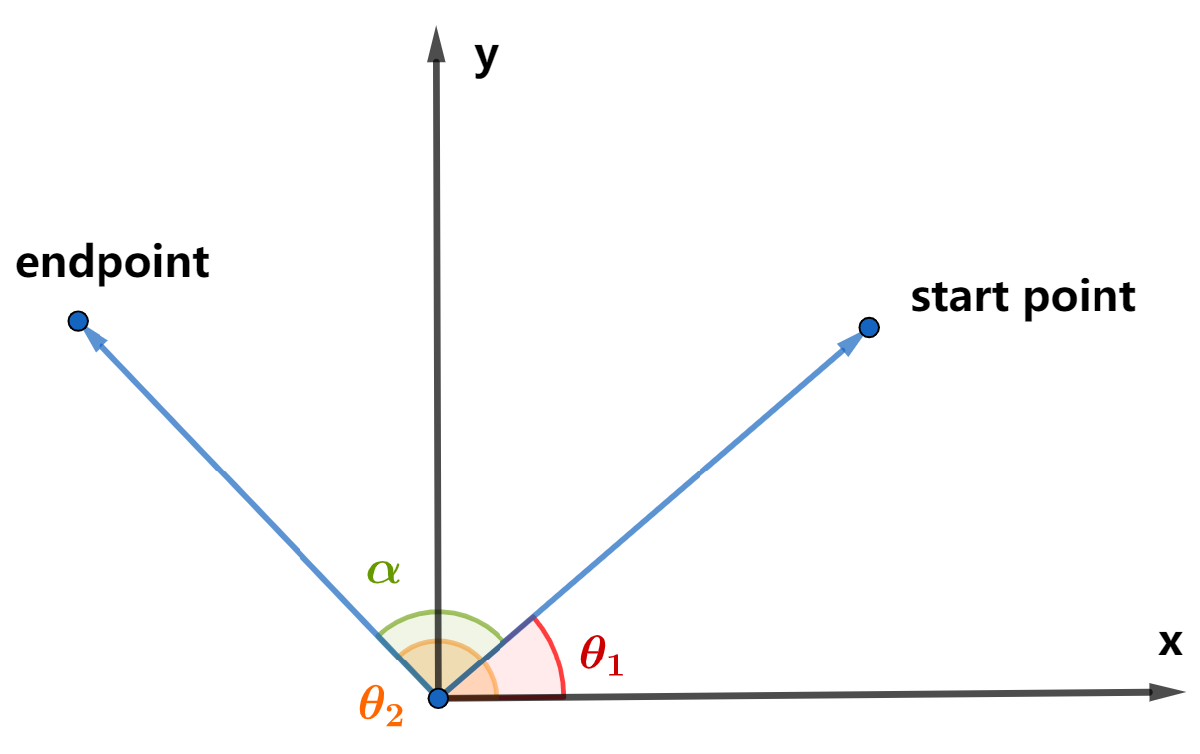

alpha = theta_2 - theta_1

% Polar coordinate
WP_end_rela = WP_end(1:2)-[x0,y0];% the coordinate of WP_end relative to circle center
WP_start_rela = WP_start(1:2)-[x0,y0];
[theta1, rho1] = cart2pol(WP_end_rela(1),WP_end_rela(2));% cartesian coordinate to polar coordinate of G1
[theta2, rho2] = cart2pol(WP_start_rela(1),WP_start_rela(2));
alpha = theta2-theta1; % calculate the angle of the arc

The angle is calculated in drivingScenarioDesigner coordinate, but in MOBATSim, the range of angle is [-pi, pi], so we should make sure the result is not out of the range:

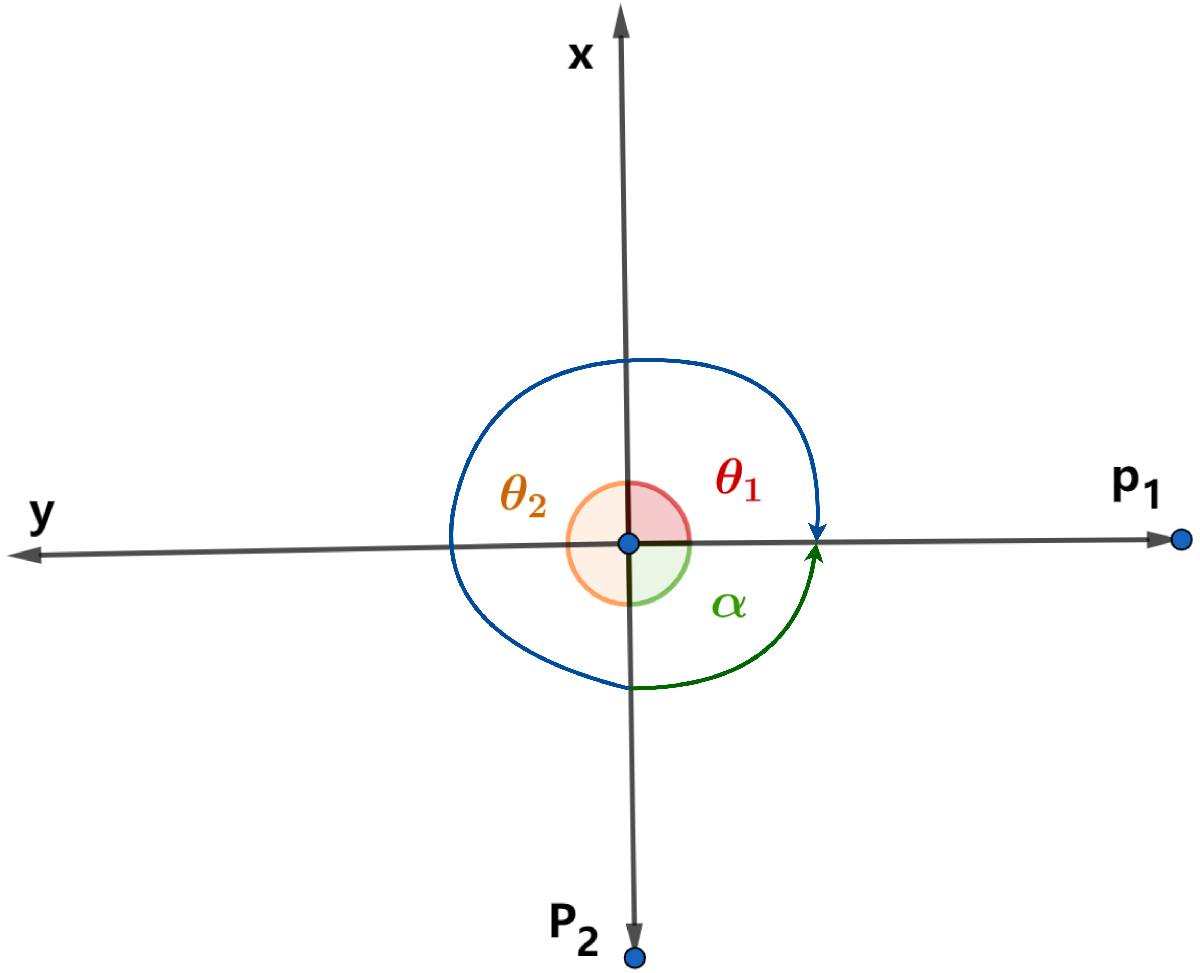

in above situation, p2 is start point, p1 is endpoint, the angle is anticlockwise. In drivingScenarioDesigner coordinate, theta_2 = pi, theta_1 = -pi/2, alpha = theta_1 - theta_2 = -3pi/2, which is not in the range. so the final result is: alpha = alpha+2pi = pi/2.

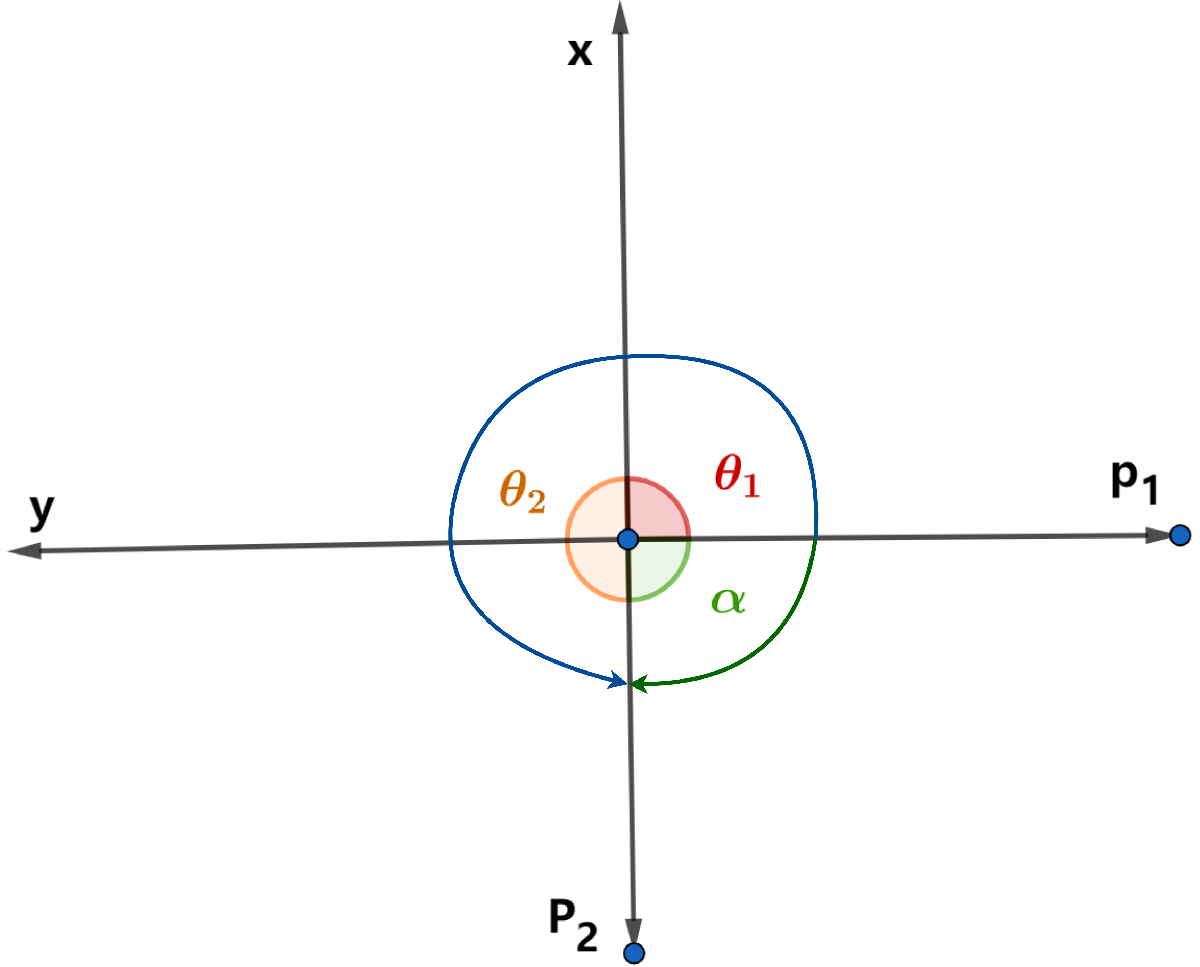

in the above situation, p1 is the start point, p2 is the endpoint, the angle is clockwise. In drivingScenarioDesigner coordinate, theta_2 = pi, theta_1 = -pi/2, alpha = theta_2 - theta_1 = 3pi/2, which is not in the range. so the final result is: alpha = alpha-2pi = -pi/2.

% the range of the angle in MOBATSim is [-pi,pi], make sure it is not out of range
if alpha>pi
    alpha = alpha-2*pi;
end
if alpha<-pi
    alpha = alpha+2*pi;
end

2.Function - "Circle_center": calculate the circle center of the curved road section, which is used in the first function.

3.Function - "Order_sequence": put the points in the extended map into the same order as the original map.

4.Function - "Route_LaneNumber": find the number of the lane for the corresponding road.

the process of this function is shown below:

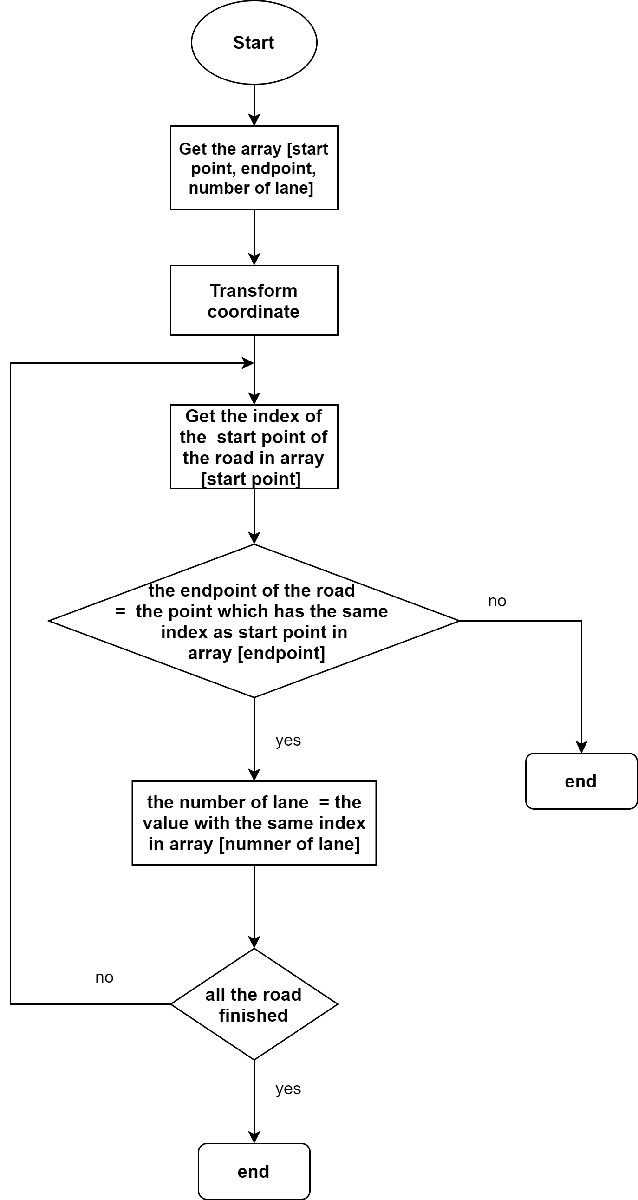

For other details in this algorithm, you can check the comment of "map_extend_v1.m"

If you just run "map_v1/map_extend_v1.m", there are four output arrays,:

When you make some changes, don't forget to check if the above output is correct.

The final output of the "map_extend_v1.m" is the form shows below:

waypoints = [x,0,-y];
connections_translation = [startpoint, endpoint, speed];% the straight road section in the map
connections_circle = [startpoint, endpoint, radian, circleCenter_x,0,-circleCenter_y, speed];% the curved road section in the map
Route_LaneNumber = [Route_id, laneNumber] % lane number of the corresponding route

Next, just add the below line in "Load Data\load_Mobatkent_from_opendrive.m"

run map_extend_v1.m

Next, load extended map in load map section in "Scripts/prepare_simulator.m" instead of the orignal one.

%% Load the Map
switch mapSelection  
    case 'Mobatkent'
        %[mapName, waypoints, connections_circle, connections_translation, ...
        %  startingNodes, breakingNodes, stoppingNodes, leavingNodes] = load_Mobatkent();
        [Route_LaneNumber, waypoints, connections_translation, connections_circle, ...
          startingNodes, breakingNodes, stoppingNodes, leavingNodes] = load_Mobatkent_from_opendrive();%load extended map
    case 'Highway'
        open_system('Platoon_Event')
        return
    
    case 'Crossmap'
        [Route_LaneNumber, mapName, waypoints, connections_circle, connections_translation, ...
          startingNodes, breakingNodes, stoppingNodes, leavingNodes] = load_Crossmap();             
end

Finally, run "prepare_simulator.m", you can get the map in the simulation.